clear all;

original = imread('Gimp.jpg');	%read image
original = imresize(original, [100 100]); %resize it to 100*100

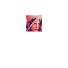

figure
imshow(original);

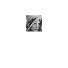

original_grayscale = rgb2gray(original); %grayscale
figure
imshow(original_grayscale);


grayscale_out = uint8(floor(double(original_grayscale))); %extract RGB values
grayscale_out = grayscale_out.';

fileID = fopen ('lena_grayscale.dat', 'w');
fprintf(fileID, '%x\n', grayscale_out(1:end));
fclose (fileID);

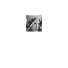

original_pepper = imnoise(original_grayscale,'salt & pepper',0.01); %pepper and salt
figure 
imshow(original_pepper);

original_pepper = uint8(floor(double(original_pepper))); %extract RGB values
original_pepper = original_pepper.'; 

fileID = fopen ('lena_pepper.dat', 'w');
fprintf(fileID, '%x\n', original_pepper(1:end));
fclose (fileID);
